***** THIS FILE IS OUTDATED: INSTEAD, PLEASE USE THE FILE M2S_exampleScript.m **

***** Rui Climaco Pinto *****

***** Imperial College London, 2020*****

# Main script example for matching two untargeted LCMS datasets

This script contains brief explanations on each step of the M2S toolbox to match metabolomics features of two untargeted datasets using RT/MZ/FI.It can load data to run two examples, shows all possibilities of inputs, and has lines of code to run to run the method on both default and defined settings.

*** To run code and create detached figures select the desired line(s) and click F9 ***

You can save this file with another name and then modify it to run your own experiments.

## Load reference and target features of sets to match

These are files containing 3 columns without headers, only values for each feature: RT, MZ, FI. NOTE: RT = median retention time ; MZ = median mass-to-charge (m/z) ratio; FI = median Feature Intensity. Note: median RT should be in minutes, if it is in seconds divide it by 60;

In case there is no feature intensity create a column with all zeros, ones or random values.

NOTE: there are two Plasma Lipid examples below, one in NEG and the other in POS mode. Only ref and target sets in the same mode can be matched.

Define the name of the files to open:

% refFilename = 'test_refFeatures_LNEG_csv.csv';
refFilename = 'test_refFeatures_LPOS_csv.csv';
% targetFilename = 'test_targetFeatures_LNEG_csv.csv';
targetFilename = 'test_targetFeatures_LPOS_csv.csv';

Function 'importdata.m' loads data from .csv, .txt, or .xlsx. 

% assuming the datasets are in current directory or are in the matlab path:
[refFeatures] = importdata(refFilename);
[targetFeatures] = importdata(targetFilename);

Visualize the two feature sets:

figure('Position',[4 577 1545 418])
subplot(1,2,1), 
M2S_plotMZRT_featureSet(refFeatures,1,8,1); title('Reference featureSet')
subplot(1,2,2), 
M2S_plotMZRT_featureSet(targetFeatures,1,8,1); title('Target featureSet')

## Part 1: find all possible matches

First create a structure to keep the options chosen at each step

opt = struct;

### Set thresholds for matching all features within those thresholds.

Try running it with default settings as below, to see the major trends. Later you can adjust each setting as you wish.

[refSet,targetSet,Xr_connIdx,Xt_connIdx, opt]=M2S_matchAll(refFeatures,targetFeatures);

#### NOTES on setting thresholds:

Thresholds define the maximum distances that the ref and target features can be in order to be matched.

You can define "horizontal line" fixed thresholds by using only "intercept" values, and setting "slope" to zero.

You can define "diagonal line" relative thresholds by adding also "slope" values.

#### HELP: this function helps to calculate an intercept and slope:

% To calculate intercept and slope from a figure using the mouse:
% *** Only works on detached figures, not on figures in the live editor***
[RTMZFI_intercept,RTMZFI_slope] = M2S_calculateInterceptSlope()
% To instead insert two points manually:
[RTMZFI_intercept,RTMZFI_slope] = M2S_calculateInterceptSlope(startPoint,endPoint)

#### Define M2S_matchAll settings and thresholds:

Example of threshold settings for LNEG test data

opt.FIadjustMethod = 'median'; % {'none','median','regression'}
opt.multThresh.RT_intercept = [-0.55,0.15];
opt.multThresh.RT_slope = [0 0];
opt.multThresh.MZ_intercept = [-0.01 0.01]; % m/z units
opt.multThresh.MZ_slope = [-5e-6 5e-6]; % ppm
opt.multThresh.log10FI_intercept = [-1000 1000];
opt.multThresh.log10FI_slope = [0 1];

Example of threshold settings for LPOS test data

opt.FIadjustMethod = 'median'; % {'none','median','regression'}
opt.multThresh.RT_intercept = [-0.1,0.1];
opt.multThresh.RT_slope = [0 0];
opt.multThresh.MZ_intercept = [-0.0075 0.015];
opt.multThresh.MZ_slope = [-0.01/2000, -0.01/2000];
opt.multThresh.log10FI_intercept = [-1.4 2.5];
opt.multThresh.log10FI_slope = [0 0];      

#### Match all features within defined thresholds

Define the plot type as:

- No plot: plotType = 0

- Scatter plot: plotType = 1

- Multiple match plot: plotType = 2 (with lines connecting multiple matches containing the same features)


 *** Executing function M2S_matchAll ***
 *** Matching all features within thresholds ***



 *** Executing function M2S_adjustFImed ***
 *** Adjusting FItarget to FImedian using the method: median ***


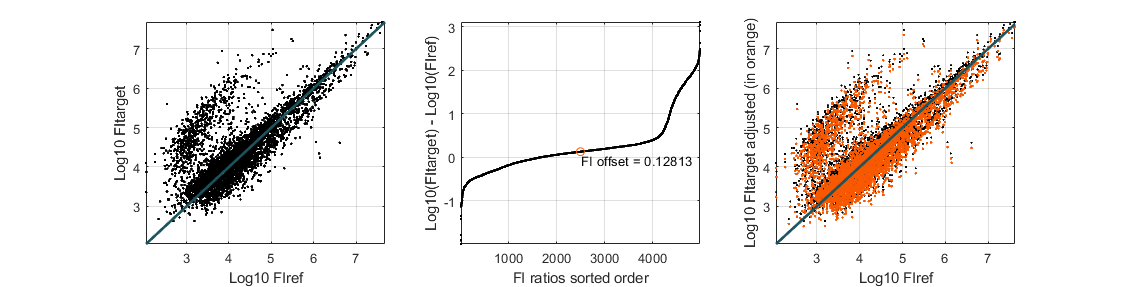

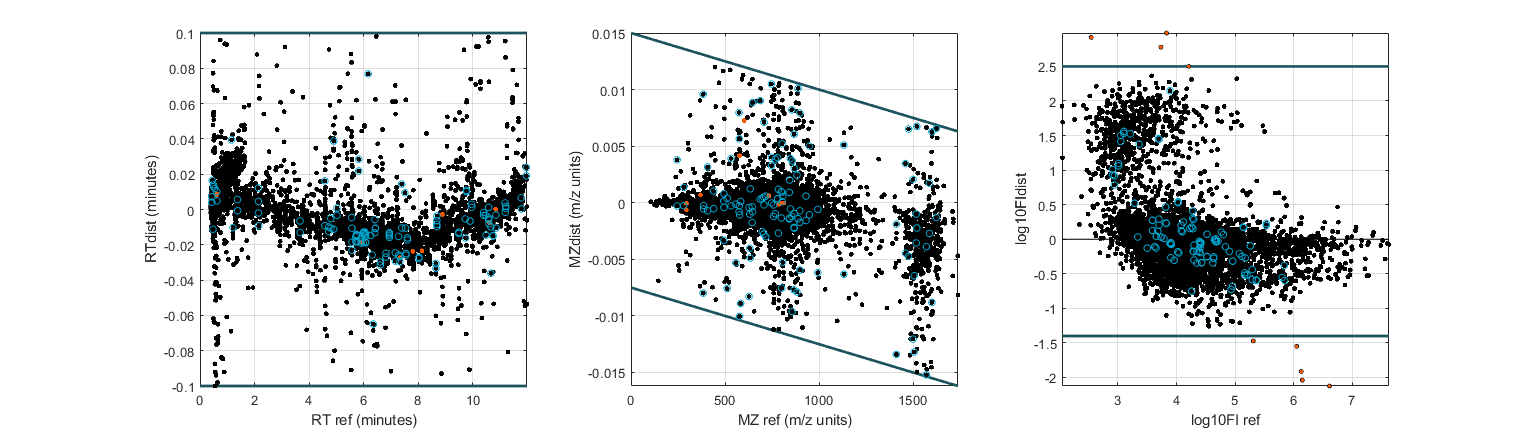

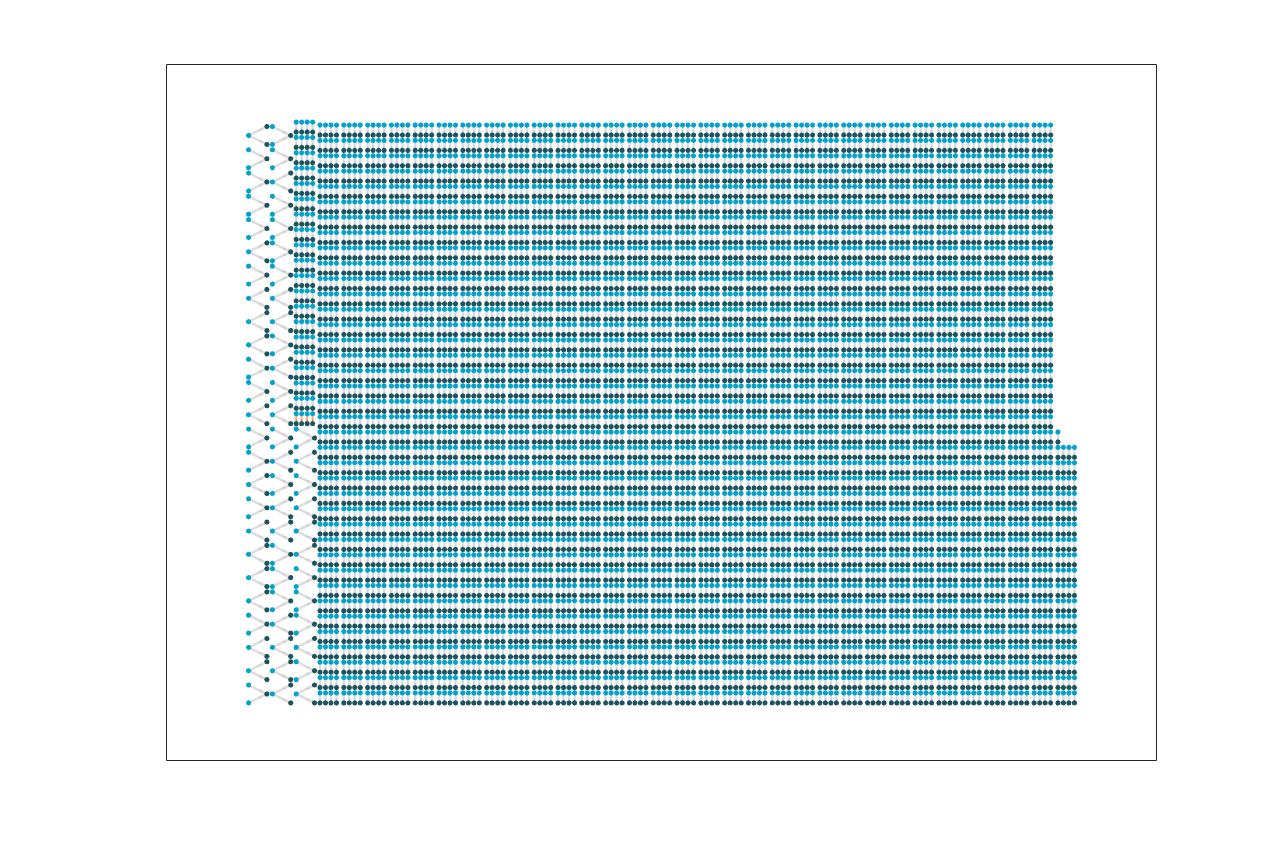

plotType = 2; % No plot = 0;  Scatter plot = 1, or Multiple match plot = 2
[refSet,targetSet,Xr_connIdx,Xt_connIdx,opt]=M2S_matchAll(refFeatures,targetFeatures,opt.multThresh,opt.FIadjustMethod,plotType);

## Procedure part 2: Calculate penalisation scores for each match

### Find neighbours, the RT/MZ/log10FI trends, and the residuals - SETTINGS OPTIONAL

- The objective here is to find the shift trends in RT/MZ/log10FI, and use it to calculate the residuals (distance to those trends).

- The method to find RT/MZ/FI shift trends uses subsets of features close to each feature (the "neighbors").

- The number of neighbours is not critical and can be defined by a percentage of the total of features in the refSet (e.g. 0.01) or by a specific number (e.g. 25).

-  The neighbor method to calculate trends can be "cross" (uses RT, MZ, FI) or (default) "circle" (which uses only RT, MZ). "Circle" does not subtract the trend from FI.

% as a percentage of the number of features in refSet: 
% opt.neighbours.nrNeighbors = 0.01; 

% as a specific number of neighbors: 
% opt.neighbours.nrNeighbors = 21; 

opt.calculateResiduals.neighMethod = 'cross'; %{'cross','circle'}

% [Residuals_X,Residuals_trendline] = M2S_calculateResiduals(refSet,targetSet,Xr_connIdx,Xt_connIdx,opt.neighbours.nrNeighbors, opt.calculateResiduals.neighMethod,1)
[Residuals_X,Residuals_trendline] = M2S_calculateResiduals(refSet,targetSet,Xr_connIdx,Xt_connIdx);

### Adjust the residuals

- The residuals are in different units and need to be standardised to allow their use to calculate the penalisation scores for each match.

-  This is done in a similar way to z-scoring (divide by stdev), by dividing by the value of the residual at a specific percentile. 

- After this division, the value of the residual at that percentile is 1, so it is easy to visualise the relevance of each of the dimension's residuals (RT/MZ/log10FI).

% opt.adjustResiduals.residPercentile = NaN % automatic determination using double MAD of Residuals_X. Different value for each dimension. BEST! 
% opt.adjustResiduals.residPercentile = 0 % automatic determination using estimation of false positive matches. Equal value for all dimensions. 
% opt.adjustResiduals.residPercentile = 80;% Value defined by user, can be between ]0,100] 
% opt.adjustResiduals.residPercentile = [75,85,100]; % Can be 0, or number between ]0,100] 

% [adjResiduals_X,residPercentile] = M2S_adjustResiduals(refSet,targetSet,Residuals_X,opt.adjustResiduals.residPercentile)
[adjResiduals_X,residPercentile] = M2S_adjustResiduals(refSet,targetSet,Residuals_X);% automatic default options

### Adjust the weight of each dimension (RT, MZ, log10FI), get penalisation scores

- It is now possible to set a weight for each of the residuals' dimensions. Many times it is desired that log10FI has weight 0.

- The penalisation scores for each match are the squared root of the sum of squares of the weighted residuals.

% opt.weights.W = [20,1,0]; % different weights 
% opt.weights.W = [1,1,1]; % equal weight opt.weights.
% W = [1,1,0]; % equal weight for RT and MZ, not using FI. Default and most used!

%[penaltyScores] = M2S_defineW_getScores(refSet,targetSet,adjResiduals_X,opt.weights.W,1)

[penaltyScores] = M2S_defineW_getScores(refSet,targetSet,adjResiduals_X); % automatic default option W = [1,1,0]

### Decide the best of the multiple matches

- This recursive method focus in a multiple-match cluster at a time, and finds in each iteration the match with the lowest penalisation score, until there are no more selections to do in that cluster.

- During the calculations you can visualise clusters with multiple matches by giving minNrNodesToPlot a small value, e.g. minNrNodesToPlot = 4.

% plotNetOrNot = 1; % 0 or 1 to plot a global network of all matches colored by the penalisation scores.
% [eL,eL_INFO,CC_G1]= M2S_decideBestMatches(refSet, targetSet, Xr_connIdx,Xt_connIdx, penaltyScores, plotNetOrNot, minNrNodesToPlot)

[eL,eL_INFO,CC_G1]= M2S_decideBestMatches(refSet, targetSet, Xr_connIdx,Xt_connIdx, penaltyScores);

## Procedure part 3: find false positives (tighten thresholds)

- The thresholds set initially are linear, and may not adapt well to curved trends. 

- Here we define tighter thresholds that can adapt to curvature.

- This will delete the matches with largest residuals.

- Notice the option 'none', which skips this step. Default is 'residuals_mad'

% To specify settings:
% opt.falsePos.methodType = 'scores'; {'none','scores','byBins','trend_mad','residuals_mad'} 
% opt.falsePos.nrMad = 5;
% plotOrNot = 1;

% [eL_final, eL_final_INFO] = M2S_findFalsePositives(eL,refSet,targetSet,opt.falsePos.methodType,opt.falsePos.nrMad,plotOrNot);

[eL_final, eL_final_INFO] = M2S_findFalsePositives(eL,refSet,targetSet);% default method residuals_mad, with nrMad = 5

Summary with number of (multiple matches) discarded, false positive and true positive matches

tableOfMatches = array2table([nansum(isnan(eL_final.notFalsePositives)),nansum(eL_final.notFalsePositives==0),nansum(eL_final.notFalsePositives==1)],'VariableNames',{'DiscardedMatches','FalsePositiveMatches','PositiveMatches'});

## RESULTS

Multiple matches not selected, false positive matches and good matches:

disp(tableOfMatches)

Table with all results : eL_final

disp(eL_final)
disp(eL_INFO)

The options used in the methods:

disp(opt)

**THE INDICES THAT MATCH refFeatures TO targetFeatures ARE:**

refFeatures_idx = eL_final.Xr_connIdx(eL_final.notFalsePositives == 1);
targetFeatures_idx = eL_final.Xt_connIdx(eL_final.notFalsePositives == 1);

### TO REORDER THE METABOLITE TABLE ACCORDING TO THESE RESULTS 

### (APPLICABLE BOTH TO NUMERICAL VALUES AND FEATURE INFO)

- After we have matched features, we need to select the corresponding data from spreadsheets/text files.

- The following lines produce MZRTstr which are strings with a unique identifier for each metabolomic feature. 

- They also produce vectors of corresponding indices which allow you to match the intensity data of reference and target datasets. 

- NOTE: features that did not match anything have the index NaN (empty) and can be deleted, as they did not match.

sorted_refIndices_idx = (1:length(refFeatures_idx))';
orderForData_Ref = NaN(size(refFeatures,1),1);
orderForData_Ref(refFeatures_idx) = sorted_refIndices_idx; 
orderForData_Ref_MZRTstr = M2S_createLabelMZRT('REF',refFeatures(:,2),refFeatures(:,1));
matchedRefData_idx = table(orderForData_Ref,orderForData_Ref_MZRTstr,'VariableNames',{'matchedIdxRef','MZRT_ref'});

sorted_targetIndices_idx = (1:length(targetFeatures_idx))';
orderForData_Target = NaN(size(targetFeatures,1),1);
orderForData_Target(targetFeatures_idx) = sorted_targetIndices_idx;
orderForData_Target_MZRTstr = M2S_createLabelMZRT('TARGET',targetFeatures(:,2),targetFeatures(:,1));
matchedTargetData_idx = table(orderForData_Target,orderForData_Target_MZRTstr,'VariableNames',{'matchedIdxRef','MZRT_target'});

#### Write a file with these two vectors:

writetable(matchedRefData_idx,'matchedRefData_idx.xlsx')
writetable(matchedTargetData_idx,'matchedTargetData_idx.xlsx')

#### To sort two data files with data (REF and TARGET) according to these indices:

0. Run the two lines above to save two tables of "matchedData_idx" (ref and target).

1. Copy 'matchedRefData_idx' and 'matchedTargetData_idx' to the datasheets (e.g. Excel, csv, etc) of ref and target you want to match, and paste them along the variables

2. Sort the variables in ascending order of the NUMERICAL indices (min to max), so the row order becomes 1, 2, 3, etc. The empty indices will be sent to the end. 

3. Delete the data for variables with empty indices (these features do not match anything)

4. Check there is the same number of variables in both datasets and these have similar (matched) RT and MZ (and FI?). Check that the MZRT_string matches the retention time and m/z of the corresponding features.

DONE!